close all; clc

syms x1 x2 real
f1 = -x1 + x1^3 + x1*x2^2;
f2 = -x2 + x2^3 + x1^2*x2;

sln = solve([f1 f2, [x1 x2]]);
sln.x1

$$ans = 0$$

sln.x2

$$ans = 0$$


% type of equilibrium point
J = jacobian([f1 f2], [x1 x2])

$$J = \left(\begin{array}{cc} 3\,{x_{1}}^{2}+{x_{2}}^{2}-1 & 2\,x_{1}\,x_{2}\\ 2\,x_{1}\,x_{2} & {x_{1}}^{2}+3\,{x_{2}}^{2}-1 \end{array}\right)$$

J(1) + J(4)

$$ans = 4\,{x_{1}}^{2}+4\,{x_{2}}^{2}-2$$

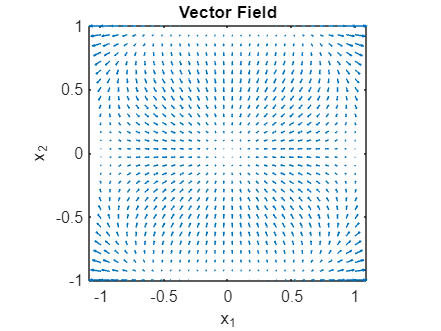

% Create vector field
close all;
x = linspace(-1,1,30);
y = linspace(-1,1,30);
[X,Y] = meshgrid(x,y);

H = max(abs(X), abs(Y));
DX = -X + X.^3 + X.*Y.^2;                 
DY = -Y + Y.^3 + X.^2*Y;

% make arrows the same length
quiver(X,Y,DX,DY,1);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

% 
% hold on; 
% plot(0, 0, 'rx')
% 
% f= @(t,P) [];
% a = [0.2 1.2];
% b = [0.2 1.2];
% for i = 1:numel(a)
%     [t,s] = ode45(f,[0 30], [a(i) b(i)]);
%     plot(s(:,1),s(:,2),'LineWidth',2)
%     plot(a(i), b(i), 'bo')
% end
% hold off 